clear all, close all, clc

############### ############### ############### ############### 

## Problem

*Calculate the radioactive decay products present and their concentrations from a room full of radon which is kept air-tight for a full 1 hour with the room being 100 m^3 in volume and the radon at a 5 pCi/L concentration. *

Let's look at following decay chain

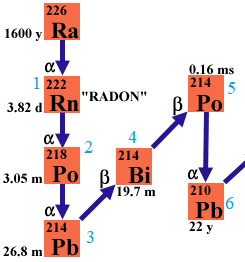


$$N_1 \overset{ \lambda_1  }{\to} N_2 \overset{ \lambda 2 }{\to} N_3 \overset{ \lambda 3 }{\to} N_4 \overset{ \lambda 4 }{\to} N_5 \overset{ \lambda 5 }{\to} N_6$$


Let's tabulate the half lives


$${\mathrm{Rn}}_{222} \left(1\right)\overset{ \lambda_1  }{\to} {\mathrm{Po}}_{218} \left(2\right)\overset{ \lambda 2 }{\to} {\mathrm{Pb}}_{214} \left(3\right)\overset{ \lambda 3 }{\to} {\mathrm{Bi}}_{214} \left(4\right)\overset{ \lambda 4 }{\to} {\mathrm{Po}}_{214} \left(5\right)\overset{ \lambda 5 }{\to} {\mathrm{Pb}}_{210} \left(6\right)$$


t_h1 = 3.82*24*60^2;    % Rn-222 ; sec
t_h2 = 3.05*60;         % Po-218 ; s
t_h3 = 26.8*60;         % Pb-214; s
t_h4 = 19.7*60;         % Bi-214
t_h5 = 0.16e-3;         % Po-214

Then, let's find the decay const

lm_1 = log(2)/t_h1      % ; s^-1

lm_1 = 2.1001e-06

lm_2 = log(2)/t_h2 

lm_2 = 0.0038

lm_3 = log(2)/t_h3 

lm_3 = 4.3106e-04

lm_4 = log(2)/t_h4

lm_4 = 5.8642e-04

lm_5 = log(2)/t_h5 

lm_5 = 4.3322e+03

Now, let's put into the generalized bateman equation,

$A_j {\left(t\right)}=N_1 {\left(0\right)}\sum_{m=1}^j C_m e^{-\lambda_m t}$     As, $C_m =\frac{\prod_{i=1}^j \lambda_n }{\prod_{\begin{array}{c}
i=1\\
i\not= m
\end{array}}^j \left(\lambda_i -\lambda_m \right)}$

**Initial Radon Concentration**

c = 5e-12;              % radon conc.; Ci/l
Bq_Ci = 37e9;           % Bq_Ci
c = c *Bq_Ci            % activity conc; Bq/l

c = 0.1850

Now, let's calculate decay rate

V = 100*1e3;         % room volume; l
A0 = c*V             % initial activity; Bq, #/s

A0 = 18500

As, $A=N\lambda \;$

N1_0 = A0/lm_1       % ; #

N1_0 = 8.8089e+09

Then, let's find the activity conc. one by one-


$${\mathrm{Rn}}_{222} \left(1\right)\overset{ \lambda_1  }{\to} {\mathrm{Po}}_{218} \left(2\right)\overset{ \lambda 2 }{\to} {\mathrm{Pb}}_{214} \left(3\right)\overset{ \lambda 3 }{\to} {\mathrm{Bi}}_{214} \left(4\right)\overset{ \lambda 4 }{\to} {\mathrm{Po}}_{214} \left(5\right)\overset{ \lambda 5 }{\to} {\mathrm{Pb}}_{210} \left(6\right)$$


**Rn-222**


$$N_1 =N_{1,0} \ e^{-\lambda_1 t}$$


t = 60*60;               % time; sec
N1 = N1_0 *exp(-lm_1*t)

N1 = 8.7426e+09

A1 = N1*lm_1            % ; Bq

A1 = 1.8361e+04

A1_c = A1/V             % activity conc.; Bq/l

A1_c = 0.1836

**Po-218**


$$N_2 =N_{1,0} \lambda_1 \ {\left[\frac{e^{-\lambda_1 t} }{\lambda_2 -\lambda_1 }+\frac{e^{-\lambda_2 t} }{\lambda_1 -\lambda_2 }\right]}$$


 fc2 = N1_0*lm_1;
 d12 = lm_2 - lm_1;
 d22 = lm_1 - lm_2;
 N2 = fc2 *(exp(-lm_1*t)/d12 + exp(-lm_2*t)/d22)

N2 = 4.8501e+06

A2 = N2*lm_2            % ; Bq

A2 = 1.8371e+04

A2_c = A2/V             % ; Bq/l

A2_c = 0.1837

**Pb-214**

 
$$N_3 =N_{1,0} \ \lambda_1 \lambda_2 {\left[\frac{e^{-\lambda_1 t} }{\left(\lambda_2 -\lambda_1 \right)\left(\lambda_3 -\lambda_1 \right)}+\frac{e^{-\lambda_2 t} }{\left(\lambda_1 -\lambda_2 \right)\left(\lambda_3 -\lambda_2 \right)}+\frac{e^{-\lambda_3 t} }{\left(\lambda_1 -\lambda_3 \right)\left(\lambda_2 -\lambda_3 \right)}\right]}$$


 fc3 = N1_0*lm_1*lm_2; 
 d13 = (lm_2 - lm_1)*(lm_3 - lm_1);
 d23 = (lm_1 - lm_2)*(lm_3 - lm_2);
 d33 = (lm_1 - lm_3)*(lm_2 - lm_3);
N3 = fc3 *(exp(-lm_1*t)/d13 + exp(-lm_2*t)/d23 + exp(-lm_3*t)/d33)

N3 = 3.2516e+07

A3 = N3*lm_3            % ; Bq

A3 = 1.4016e+04

A3_c = A3/V             % ; Bq/l

A3_c = 0.1402

**Bi-214**


$$N_4 =N_{1,0} \ \lambda_1 \lambda_2 \lambda_3 {\left[\frac{e^{-\lambda_1 t} }{\left(\lambda_2 -\lambda_1 \right)\left(\lambda_3 -\lambda_1 \right)\left(\lambda_4 -\lambda_1 \right)}+\frac{e^{-\lambda_2 t} }{\left(\lambda_1 -\lambda_2 \right)\left(\lambda_3 -\lambda_2 \right)\left(\lambda_4 -\lambda_2 \right)}+\frac{e^{-\lambda_3 t} }{\left(\lambda_1 -\lambda_3 \right)\left(\lambda_2 -\lambda_3 \right)\left(\lambda_4 -\lambda_3 \right)}+\frac{e^{-\lambda_4 t} }{\left(\lambda_1 -\lambda_4 \right)\left(\lambda_2 -\lambda_4 \right)\left(\lambda_3 -\lambda_4 \right)}\right]}$$


 fc4 = N1_0*lm_1*lm_2*lm_3; 
 d14 = (lm_2 - lm_1)*(lm_3 - lm_1)*(lm_4 - lm_1);
 d24 = (lm_1 - lm_2)*(lm_3 - lm_2)*(lm_4 - lm_2);
 d34 = (lm_1 - lm_3)*(lm_2 - lm_3)*(lm_4 - lm_3);
 d44 = (lm_1 - lm_4)*(lm_2 - lm_4)*(lm_3 - lm_4);
N4 = fc4 *(exp(-lm_1*t)/d14 + exp(-lm_2*t)/d24 + exp(-lm_3*t)/d34 + exp(-lm_4*t)/d44)

N4 = 1.5573e+07

A4 = N4*lm_4            % ; Bq

A4 = 9.1325e+03

A4_c = A4/V             % ; Bq/l

A4_c = 0.0913

**Po-214**

Here, activity would be the same